[s,fs]=audioread('test_16k.wav');
fsout=10000;

%resample
s_resample=resample(s,fsout,fs);

%bandpass
Hd=bandpassfilter_problem2;
s_resample_bandpass=filter(Hd,s_resample);

%save speech file
audiowrite('original resampled speech.wav',s_resample,fsout);

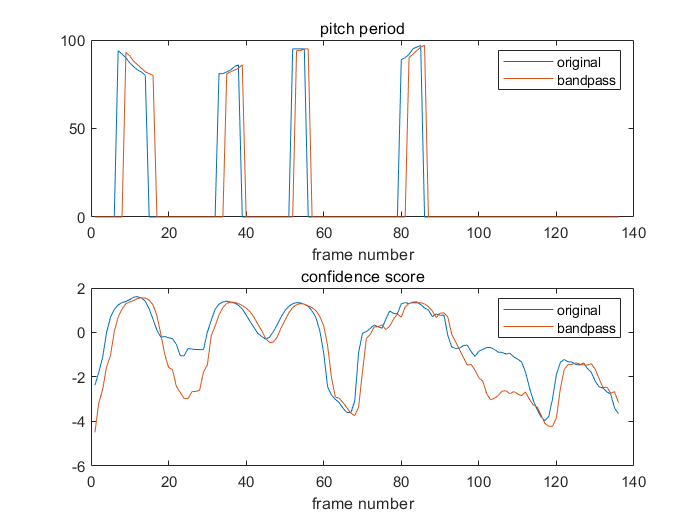

audiowrite('original resampled bandpassed speech.wav',s_resample_bandpass,fsout);

%operation
[pitch_period_original,pitch_period_medianfilter_original,score_log_original,score_log_medianfilter_original]=PicthDetector_Autocorrelation(s_resample,fsout,"male");
[pitch_period_bandpass,pitch_period_medianfilter_bandpass,score_log_bandpass,score_log_medianfilter_bandpass]=PicthDetector_Autocorrelation(s_resample_bandpass,fsout,"male");
save('pitch_period_medianfilter_original.mat','pitch_period_medianfilter_original');
save('score_log_medianfilter_original.mat','score_log_medianfilter_original');
save('pitch_period_medianfilter_bandpass.mat','pitch_period_medianfilter_bandpass');
save('score_log_medianfilter_bandpass.mat','score_log_medianfilter_bandpass');

figure
subplot(2,1,1);
plot(pitch_period_original);
hold on;
plot(pitch_period_bandpass);
title('pitch period');
xlabel('frame number');
legend('original','bandpass');
subplot(2,1,2);
plot(score_log_original);
hold on;
plot(score_log_bandpass);
title('confidence score');
xlabel('frame number');
legend('original','bandpass');

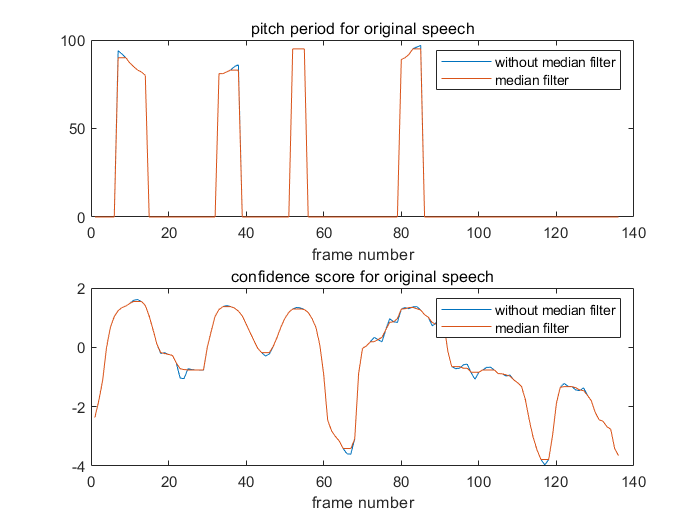


figure;
subplot(2,1,1);
plot(pitch_period_original);
hold on;
plot(pitch_period_medianfilter_original);
title('pitch period for original speech');
xlabel('frame number');
legend('without median filter','median filter');
subplot(2,1,2);
plot(score_log_original);
hold on;
plot(score_log_medianfilter_original);
title('confidence score for original speech');
xlabel('frame number');
legend('without median filter','median filter');

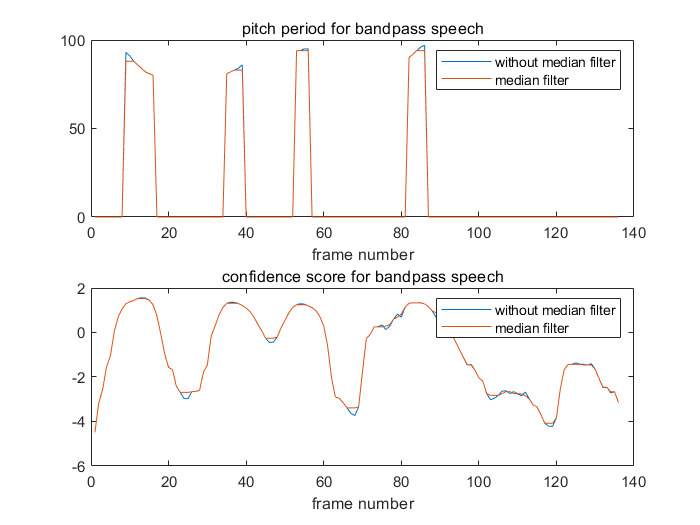


figure;
subplot(2,1,1);
plot(pitch_period_bandpass);
hold on;
plot(pitch_period_medianfilter_bandpass);
title('pitch period for bandpass speech');
xlabel('frame number');
legend('without median filter','median filter');
subplot(2,1,2);
plot(score_log_bandpass);
hold on;
plot(score_log_medianfilter_bandpass);
title('confidence score for bandpass speech');
xlabel('frame number');
legend('without median filter','median filter');